# Fireball modelization example 

In this example, we will introduce the several functions implemented for fireball modelization. 

clear
clc

## 1. Initialization of model parameters 

gas_frac =  .85 ; %fraction of gas inside the vessel [0-1]
combustion_heat = 46000 ; % heat of combustion of flamable substance - KJ/Kg
density = 517 ;  % of flamable substance - kg/m3
Psv= 1.6 ;  % vapour pressure inside the vessel in MPa
vessel_volume =  50 ; % in m3 
Pow  = 2320 ; % saturation vapour pressure in the air in Pa
RH = 0.7 ; % humidity ratio in [0-1]
N0 = 0.05 ; % population density in the area - ppl / m²

**Resolution of computations for heatflux & thermal effects  :** A higher value => smaller step => slower execution 

Indicative values :  125  - 250 - 500 

Resolution = 125 ; % 125 250 500 

**Body coverage : ** Impact of clothes on thermal radiation :  

0.94  : summer clothes  - small mitigation 

0.14 : winter clothes - mitigation 

1 : ignore clothes impact

Fk = 1 ; 

**Safety factor : **over-estimate heatflux value 

safety_factor = 1 ; % 1 or 2 


## 2. Computations 

Initial mass of flamable substance in **Kg** :


initial_mass = initial_mass_computation(gas_frac,vessel_volume,density) 

initial_mass = 2.1973e+04

Max diameter of fireball and its duration  

D_max in **meters** 

t_max in **seconds** 

[D_max , t_max] = max_parameters_computation_TNO(initial_mass) 

D_max = 167

t_max = 11.5000

fireball_height = D_max 

fireball_height = 167

Burning rate in **kg/s**

burning_rate = burning_rate_computation(D_max,t_max,initial_mass)

burning_rate = 0.0246

Surafce emmitting power in **kW/m² **

SEP = SEP_computation(Psv,burning_rate,combustion_heat) 

SEP = 354.9322

**Compute heat flux for various distances from flame center **

**heat_flux_batch1D :  Heatflux array in kW/m²  **

**R_1D : Distances in meters **

[R_1D,heat_flux_batch1D] = batch_heat_flux_computation_1D(D_max,Resolution,fireball_height,Pow,RH,SEP );
 if(safety_factor > 1)
    heat_flux_batch1D = safety_factor.*heat_flux_batch1D ;
 end


**2D map of heatflux  repartition **

 [X,Y,heat_flux_batch2D] = batch_heat_flux_computation_2D(D_max,Resolution,fireball_height,Pow,RH,SEP );
 if(safety_factor > 1)
    heat_flux_batch2D = heat_flux_batch2D.*safety_factor; 
 end
 
 
% curve fitting 
 [heatflux_from_distance_fit, gof] = fit_get_heatflux(R_1D, heat_flux_batch1D);

 str ={formula(heatflux_from_distance_fit),' parameters resp : ',num2str(coeffvalues(heatflux_from_distance_fit)),'R^2 = ',gof.rsquare };
 [distance_from_heatflux_fit] = fit_get_distance(heat_flux_batch1D, R_1D);

**Compute probabilities of injury for various distances using probit functions  : **

Level 1 skin burns - Level 2 - Death 

As well as overall effects : an estimation of overall deaths and injuries in the area given the population density 

 % Thermal effects 
 ovr_injuries_lv1 = 0 ;  % level 1 skin burns 
 ovr_injuries_lv2 = 0 ;  % level 2 
 ovr_injuries_lv3 = 0 ;  % deaths 
 
 [P_level1_1d_batch,P_level2_1d_batch, P_level3_1d_batch ] = batch_ppl_effect_computation_1D(t_max,Fk,R_1D,  D_max , distance_from_heatflux_fit  ,heatflux_from_distance_fit);
 [ovr_injuries_lv1,ovr_injuries_lv2,ovr_injuries_lv3] = overall_effects_computation(N0,D_max,R_1D,P_level1_1d_batch,P_level2_1d_batch, P_level3_1d_batch,distance_from_heatflux_fit);
 
 

2D map of spacial repartition of probabilities of injury/death 

 [P_level1_2d_batch , P_level2_2d_batch ,  P_level3_2d_batch] = batch_ppl_effect_computation_2D(t_max,Fk, X,Y,D_max , distance_from_heatflux_fit  ,heatflux_from_distance_fit);


## 3. Ploting results 

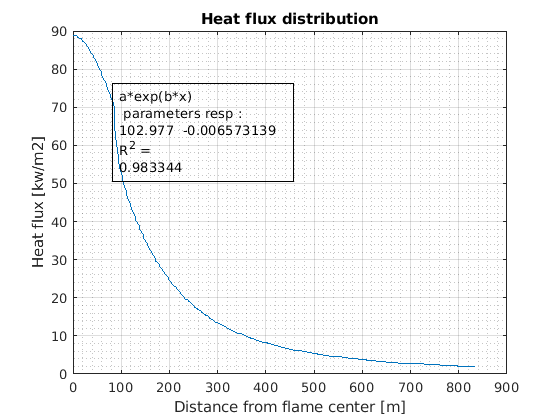

  
 plot1Dheatflux(R_1D,heat_flux_batch1D,str);

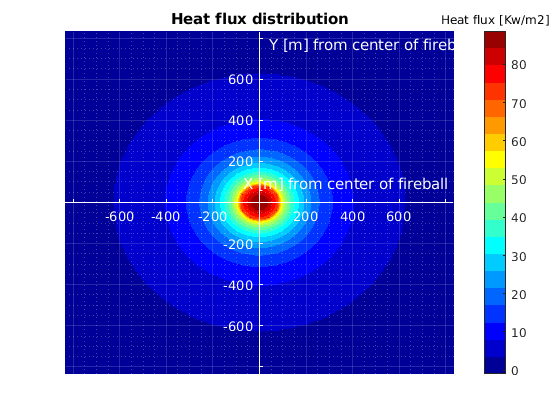

 plotHeatMap(X,Y,heat_flux_batch2D) ;

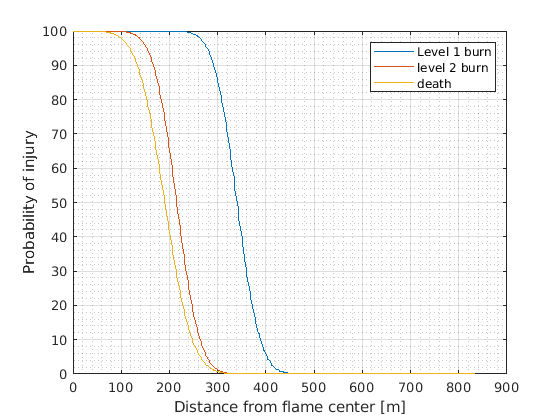

  plot_ppl_effects(R_1D,P_level1_1d_batch,P_level2_1d_batch, P_level3_1d_batch);

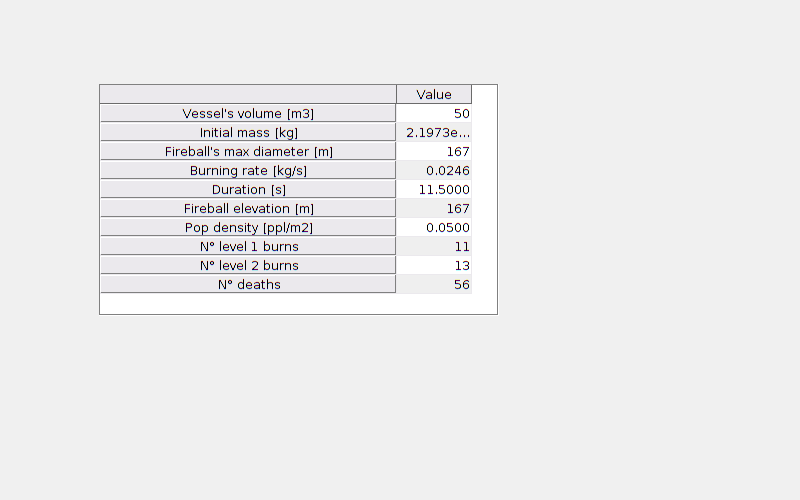

plot_heatmap_injuries(X,Y,P_level1_2d_batch , P_level2_2d_batch ,  P_level3_2d_batch);
 
 
 
Sim_array = [ vessel_volume ;initial_mass  ; D_max ; burning_rate ; t_max ; fireball_height ;   N0;ovr_injuries_lv1;ovr_injuries_lv2;ovr_injuries_lv3];
fx = figure('Name','Overview');
fx.Resize = 'off';
fx.Position(3) = 800; 
fx.Position(4) = 500;
%fx.ToolBar = 'none';
%fx.MenuBar = 'none';
uit = uitable(fx,'Data',Sim_array,'Position',[fx.Position(1)*0.25  fx.Position(2)*0.75 fx.Position(3)*0.5 fx.Position(4)*0.465]);
uit.ColumnName = {'Value'};
uit.RowName = {'Vessel''s volume [m3]','Initial mass [kg]','Fireball''s max diameter [m]','Burning rate [kg/s]','Duration [s]','Fireball elevation [m]','Pop density [ppl/m2]','N° level 1 burns','N° level 2 burns','N° deaths'};